# Solving the Knapsack Problem with QUBO and Ansatz

## Problem description

Data: $n$ objects $x_i$ with respective $\left(v_i ,w_i \right)$

Where $v_i = \text{value of } x_i$  ;  $w_i = \text{weight of } x_i$

Constraint: Limited Knapsack capacity

## Formulation as a Decision Problem


$$\text{Objective Function:}
\[
\max \sum_{i=1}^n v_i x_i
\]
Subject to constraint:
\[
\sum_{i=1}^n w_i x_i \leq C
\]
where:
\[
x_i \in \{0, 1\} \quad \forall i
\]
\( C \) = Max Knapsack Capacity$$


The following code initializes the data for the problem:

w = [2 2 9];  % weights
v = [10 10 50]; % values
capacity = 10;  % maximum capacity  
N = length(v);

### Objective Function with Penalty


$$\[
f = \sum_{i=1}^n v_i x_i - P \left( \sum_{i=1}^n w_i x_i - C \right)^2
\]$$



$$\text{We fix the penalty as } P= 5\sum_{i=1}^n v_i  

 $$



$$\text{to ensure that the penalty is always more relevant 
than the total value of the solution (even when all objects are taken)$$


P = 5*sum(v);

### Vector formulation


$$\text{Define:}
\[
\mathbf{w} = [w_1, w_2, \dots, w_n] \in \Re_+^n  
\]
\[
\mathbf{v} = [v_1, v_2, \dots, v_n] \in \Re^n
\]
\[
\mathbf{x} = [x_1, x_2, \dots, x_n]^T \in \{0,1\}^n 
\]

We can rewrite the objective function with penalty as:
\[
f = \mathbf{v} \mathbf{x} - P \left( \mathbf{w} \mathbf{x} - C \right)^2 =
\]
\[
= \mathbf{v} \mathbf{x} 
    - P \left( 
        \mathbf{x}^T\mathbf{w}^T\mathbf{w} \mathbf{x}  
        - 2C\mathbf{w}\mathbf{x} + C^2
    \right)
\]$$


**Note**: the constant term $-P C^2$ is irrelevant.

## Qubo Formulation


$$\[
f = \mathbf{x}^T D\mathbf{x} + \mathbf{c} \mathbf{x}
\]
where:
\[
D := -P \mathbf{w}^T \mathbf{w} \in \text{Mat($n$,$n$)}, 
\quad \mathbf{c} := (\mathbf{v} + 2PC\mathbf{w}) \in \Re^n
\]
$$



$$\text{Since:}
\[
\mathbf{c}\mathbf{x} \in \Re \ ,\ \mathbf{x} \in \{0,1\}^n
\]
\[
\mathbf{c}\mathbf{x} = \mathbf{x}^T diag(\mathbf{c}) \ \mathbf{x}
\]



$$



$$\text{We can rewrite the QUBO formulation as:}
\[
f = \mathbf{x}^T Q \mathbf{x}
\]
where: 
\[
Q = D \ +\ diag(c)
\]
$$


D = -P * (w' * w);
c = v + 2*P*capacity*w;

Q = D + diag(c);

### Qubo solver

The following code runs QUBO with the data defined above and displays the best solution:

qubo_prob = qubo(-Q); % Q is negated because qubo minimizes the obj function.
result = solve(qubo_prob, Algorithm=qaoa); 

bestVal = result.BestFunctionValue;
bestX = result.BestX;

if w*bestX > capacity
    disp("solution found is invalid, the total weight is over maximum capacity");
end
disp("BestX = ")
disp(bestX')

bestFunc = v*bestX;
fprintf("Best obj. value = %.2f\n", bestFunc)

## Ising Model


$$\text{We move from QUBO Formulation to the Ising Model Hamiltonian by substituting:}
\[
\mathbf{x} = \frac{\mathbf{I} - \mathbf{\overline{\sigma}}}{2}
\]

where:
\[
\mathbf{I} = [I_1, I_2, \dots, I_n]=\text{vector of Identity Gates}
\]
\[
\overline{\sigma} = [\sigma^Z_1, \sigma^Z_2, \dots, \sigma^Z_n] = \text{vector of Pauli Z gates}
\]
$$



$$\text{Substituting into the objective function:}

\[
f\left( \frac{\mathbf{I} - \overline{\sigma}}{2} \right) = \left( \frac{\mathbf{I} - \overline{\sigma}}{2} \right)^T Q \left( \frac{\mathbf{I} - \overline{\sigma}}{2} \right) = ... = \frac{1}{4} \left( -\sum_{i,j}(q_{ij}+ q_{ji} ) \sigma_i \space\space + \sum_{i,j} q_{ij}\sigma_i\sigma_j \right)
\]$$


**Note:** a constant term $\mathbf{I}^T Q \mathbf{I}$ was omitted for simplicity, since a constant energy shift is irrelevant.

### Hamiltonian


$$$\frac{1}{4}$ is also removed for simplicity because a constant coefficient is irrelevant for the Hamiltonian.

By defining:
\[
h_i =  -\sum_{j=1}^n q_{ij}+ q_{ji}
\]
\[
J = Q
\]

We obtain the standard form of the Ising Model cost Hamiltonian:
\[
H_C = \sum_{i,j} J_{ij} \sigma_i^z \sigma_j^z + \sum_i h_i \sigma_i^z
\]

$$


J = Q; 
    
h1 = sum(Q,2); % Sum over j of q_ij
h2 = sum(Q,1); % Sum over j of q_ji
h = -(h1+h2);

## Ansatz Circuit


$$\text{The Ansatz circuit is described by the operator: }
\[
A(\vec{\beta}, \vec{\gamma}) = \left( \prod_{k=1}^r U(H_X \beta_k) U(H_C, \gamma_k) \right) H^{\otimes{n}}
\]

where $r=$ number of layers.$$



$$\text{The layers are composed by two parts: the mixing gate } U(H_X \beta_k), \text{and the cost gate } U(H_C\gamma_k).
$$



$$
\text{The gates } U(x) \text{ are defined as } U(x) = e^{-ix}.$$



$$\text{The Cost Hamiltonian was defined above as the Hamiltonian of the Ising Model } H_C.

$$



$$\text{The Mixing Hamiltonian } H_X \text{ is defined as follows:}
\[
H_X = \sum_{i=1}^n \sigma_i^x
\]
Where $\sigma_i^x$ is the Pauli X gate.$$



$$\text{The mixing gates become } R_x \text{ gates of parameter } 2\beta_k.$$



$$\text{The cost gates become:}
\[
U(H_C, \gamma_k) = e^{-i\gamma_kH_C} 
= \prod_{i=1}^n e^{-i\gamma_k h_i \sigma_i^z} 
  \prod_{i,j=1}^n e^{-i\gamma_k J_{ij} \sigma_i^z \sigma_j^z}
= \prod_{i=1}^n R_Z(2\gamma_k h_i) 
  \prod_{i,j=1}^n R_{ZZ}(2\gamma_k J_{ij})
\]
where the $R_{ZZ}$ gates of parameter $2\gamma_k J_{ij}$ are applied to qubits $i,j$.$$


numLayers = 2;
angles = pi*ones(2,numLayers); % given a set of angles
ansatz = qaoaCircuit(N, h, J, angles, numLayers);
plot(ansatz);

### Ansatz Optimization

We then use MATLAB's Global Optimization Toolbox to find the optimal set of angles $$\vec{\beta}, \vec{\gamma}$$ that yield the optimal solution of the problem.

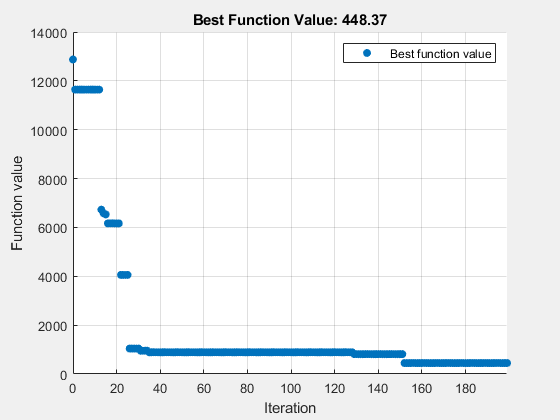

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


rng(10) % For reproducibility
numLayers = 2;
numShots = 1000;

%function to maximize
objFcn = @(theta) -expectedObjectiveValue(N, h, J, v, w, P, capacity, theta, numLayers,numShots); 

%bound is a column vector of 2*numLayers elements with pi in each element
bound = repmat(pi,2*numLayers,1); 

% initial guess for angles (set all to pi)
x0Theta = pi*ones(2,numLayers); 
% max evaluations for the global optimizer
maxEvaluations = 200;
options = optimoptions("surrogateopt",InitialPoints=x0Theta,MaxFunctionEvaluations=maxEvaluations);
[angles,bestfval] = surrogateopt(objFcn,-bound,bound,[],[],[],[],[],options); %compute best angles

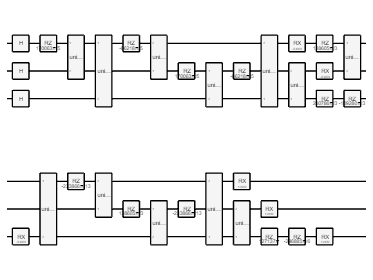


optimizedCircuit = qaoaCircuit(N,h,J,angles,numLayers);

figure(1)
plot(optimizedCircuit)

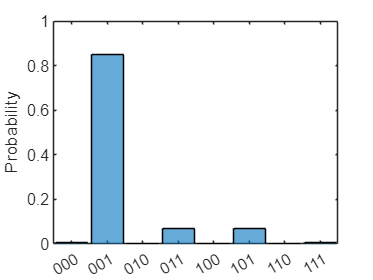


sv = simulate(optimizedCircuit);
histogram(sv)

meas = randsample(sv,1000);

[states, probabilities] = querystates(meas);
[maxValue, index] = max(probabilities);
states_matrix = double(char(states) == '1');
bestX = states_matrix(index, :);

disp("bestX = ");

bestX = 


disp(bestX);

     0     0     1




disp("bestValue = ");

bestValue = 


disp(bestX*v');

    50

